# Simulation

## Environment

To be the as realistic as possible in simulation we've downloaded real scans of Italy mountains (area W51570 from INGV [https://tinitaly.pi.ingv.it/Download_Area1_1.html).](https://tinitaly.pi.ingv.it/Download_Area1_1.html).)

From this large area we select the top-right 1/16 square, and from this the bottom left 1/16 square

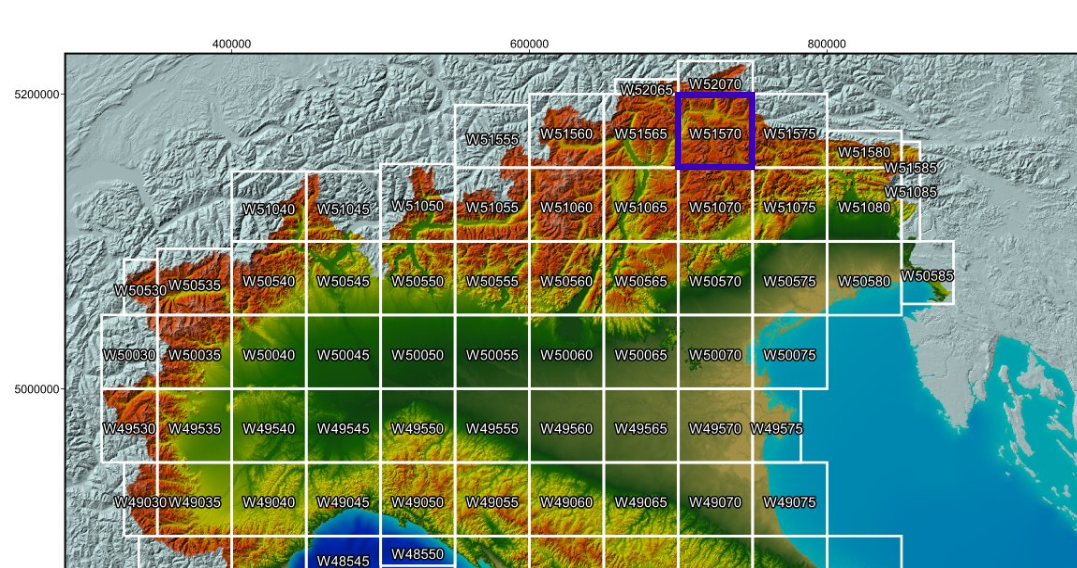

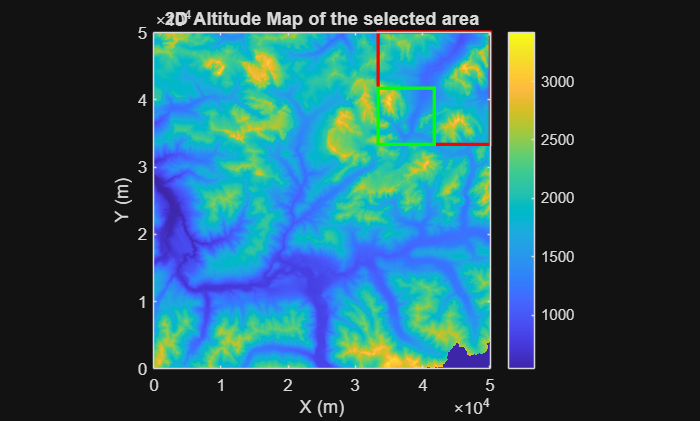

[Z, R] = readgeoraster('map.tif');
Z = double(Z);

x = linspace(R.XWorldLimits(1), R.XWorldLimits(2), size(Z,2)); 
y = linspace(R.YWorldLimits(1), R.YWorldLimits(2), size(Z,1));
x = x - x(1);
y = y - y(1);
[X, Y] = meshgrid(x,y);

figure, clf;
imagesc(x, y, Z)    
set(gca, 'YDir', 'normal')  
xlabel('X (m)')
ylabel('Y (m)')
title('2D Altitude Map of the selected area')
colormap(parula)
colorbar
axis equal tight
hold on

% Dimensions
[nRows, nCols] = size(Z);

% --- First square: top-right 1/16 ---
rowRange1 = round(2*nRows/3) : nRows;
colRange1 = round(2*nCols/3) : nCols;

x1 = x(colRange1(1));
y1 = y(rowRange1(1));
w1 = x(colRange1(end)) - x(colRange1(1));
h1 = y(rowRange1(end)) - y(rowRange1(1));

rectangle('Position', [x1, y1, w1, h1], ...
          'EdgeColor', 'r', 'LineWidth', 2)

% --- Second square: bottom-left of the first ---
subZ = Z(rowRange1, colRange1);
[subRows, subCols] = size(subZ);

rowRange2 = 1 : round(subRows/2);
colRange2 = 1 : round(subCols/2);

% Converti negli indici globali
rowRange2_global = rowRange1(rowRange2);
colRange2_global = colRange1(colRange2);

% Coordinate reali rettangolo 2
x2 = x(colRange2_global(1));
y2 = y(rowRange2_global(1));
w2 = x(colRange2_global(end)) - x(colRange2_global(1));
h2 = y(rowRange2_global(end)) - y(rowRange2_global(1));

rectangle('Position', [x2, y2, w2, h2], ...
          'EdgeColor', 'g', 'LineWidth', 2)

Now from the selected (green) area we choose another area that will be the actual operational environment, the avalanche zone. In the development part it will be a fixed zone, in the testing phase it will be randomly chosen within the selected (green) area.

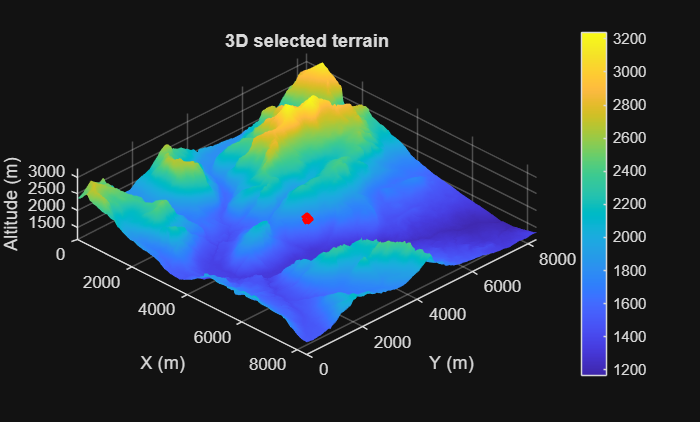

% --- Extract the final square (green one) ---
Z_sel = Z(rowRange2_global, colRange2_global);
X_sel = X(rowRange2_global, colRange2_global);
Y_sel = Y(rowRange2_global, colRange2_global);

X_sel = X_sel - X_sel(1);
Y_sel = Y_sel - Y_sel(1);

% --- 3D plot ---
figure, clf;
surf(X_sel, Y_sel, Z_sel)

shading interp          
colormap(parula)
colorbar

xlabel('X (m)')
ylabel('Y (m)')
zlabel('Altitude (m)')
title('3D selected terrain')

axis equal
view(45,30)
hold on

% --- Workspace dimension [m] ---
L = 150;

% --- Choose a position (eventually random) ---
x0 = (max(X_sel(:)) - L)/2;
y0 = (max(Y_sel(:)) - L)/2;

% square corners
x_sq = [x0 x0+L x0+L x0 x0];
y_sq = [y0 y0 y0+L y0+L y0];

% project on the 3d surface
z_sq = interp2(X_sel, Y_sel, Z_sel, x_sq, y_sq);

% --- Draw the projected square ---
plot3(x_sq, y_sq, z_sq, 'r-', 'LineWidth', 3)

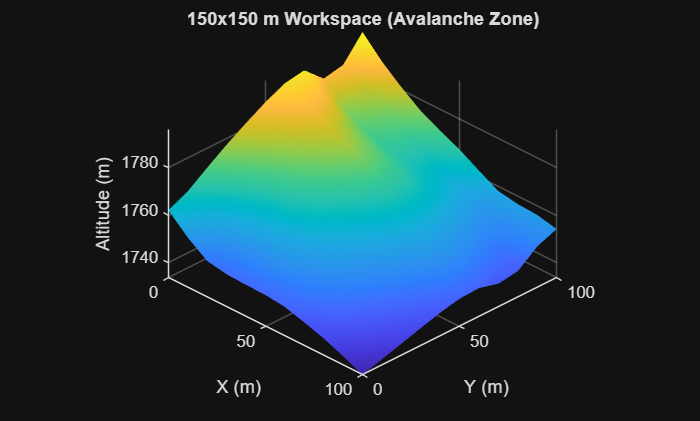

% Trova indici dentro il range 150x150
idx_x = find(x >= x0 & x <= x0 + L);
idx_y = find(y >= y0 & y <= y0 + L);

% Estrai sottosezione
X_ws = X_sel(idx_y, idx_x);
Y_ws = Y_sel(idx_y, idx_x);
Z_ws = Z_sel(idx_y, idx_x);

X_ws = X_ws - X_ws(1);
Y_ws = Y_ws - Y_ws(1);

% define the function of the slope ([x,y]->z)
F = griddedInterpolant(X_ws', Y_ws', Z_ws', 'linear', 'nearest');

xgg = linspace(0, 100, 100);
ygg = linspace(0, 100, 100);
[Xgg, Ygg] = ndgrid(xgg, ygg);

% Final simulation environment
figure, clf;

surf(Xgg, Ygg, F(Xgg, Ygg))
shading flat
view(45,30)
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Altitude (m)')
title('150x150 m Workspace (Avalanche Zone)')
axis equal

## Drone motion

For the moment the drone is modeled as a point mass controlled with an applied force, as we will first focus on the control and communication part

%-----SIMULATION PARAMS-----
m = 1.5;    % Drone mass

kp = 1000;  % Proportional gain
kd = 100;   % Derivative gain

dt = 0.01;  % Time step

N = 10000;    % Number of simulated time steps
t0 = 0;     % Initial time
tf = t0 + N*dt; % Final time
t = linspace(t0, tf, N);    % Time vector

%-----REFERENCE TRAJECTORY FOR EXPLORATION-----
% When the drone is deployed, it starts exploring the environment looking
% for the ARTVA magnetic signal.
% The trajectory is an Archimedean spiral

a = 0.1;      % Inital radius
b = 1;      % Distance between consecutive laps (density)
v_ref = 5.0;  % Desired speed (m/s)

theta = zeros(size(t));

for k = 2:length(t)
    r = a + b*theta(k-1); % Linearly increasing radius
    
    theta_dot = v_ref / sqrt(b^2 + r^2);
    
    theta(k) = theta(k-1) + theta_dot * dt;
end

r = a + b*theta;    

x_ref = 50 + r .* cos(theta);
y_ref = 50 + r .* sin(theta);
xd_ref = gradient(x_ref, dt);
yd_ref = gradient(y_ref, dt);

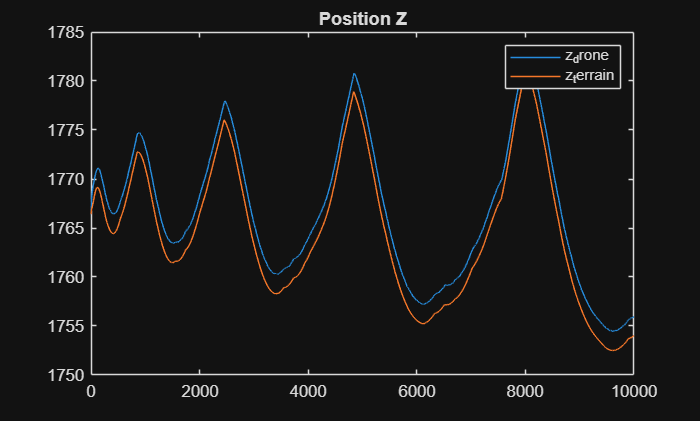

% then we build a simple P controller to control the force correctly:

% Start from "middle"
% Set Workspace
% Take Off
% Start Drone Measure
% Start Exploration (need measure)


s0 = [x_ref(1), y_ref(1), F(x_ref(1), y_ref(1)), xd_ref(1), yd_ref(1), 0];
s_res = zeros(N,6);
s_res(1,:) = s0;
for k = 1:N-1
    % measure
    z_meas = F(s_res(k, 1:2)) + 0.1*randn(1,1);
    % trajectory calculation
    s_ref = [x_ref(k), y_ref(k), z_meas + 2, xd_ref(k), y_ref(k), 0];
    % control
    u = kp*(s_ref(1:3) - s_res(k, 1:3)) + kd*(s_ref(4:6) - s_res(k, 4:6));
    % drone dynamic
    s_res(k+1,:) = DroneForwardDynamicsStep(s_res(k,:), u , m, dt);
end


% we want to compare the actual z coordinate with the desired one in time
figure;
plot(s_res(:,3)); 
title('Position Z');
hold on
plot(F(s_res(:, 1:2))); 
legend('z_drone', 'z_terrain')

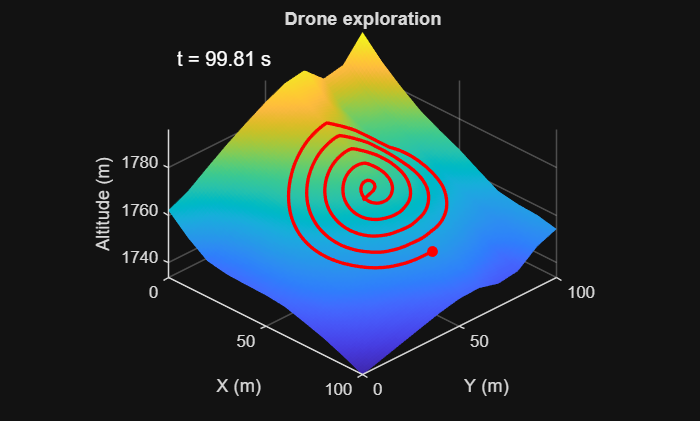

ds = 20;  % Downsampling for the animation (1 sample every ds samples)
s_res_ds = s_res(1:ds:end, :);
t_ds = t(1:ds:end);

figure, clf;

surf(Xgg, Ygg, F(Xgg, Ygg))
shading flat
view(45,30)
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Altitude (m)')
title('Drone exploration')
axis equal
hold on

h_traj = plot3(NaN, NaN, NaN, 'r', 'LineWidth', 2);
h_point = plot3(NaN, NaN, NaN, 'ro', 'MarkerFaceColor', 'r');

% testo tempo
h_text = text(0.02, 0.95, '', ...
    'Units', 'normalized', ...
    'FontSize', 12, ...
    'Color', 'w', ...
    'VerticalAlignment', 'top');

for k = 1:length(s_res_ds)
    % aggiorna traiettoria
    set(h_traj, 'XData', s_res_ds(1:k,1), ...
                'YData', s_res_ds(1:k,2), ...
                'ZData', s_res_ds(1:k,3));
    
    % punto corrente
    set(h_point, 'XData', s_res_ds(k,1), ...
                 'YData', s_res_ds(k,2), ...
                 'ZData', s_res_ds(k,3));
    
    % aggiorna tempo (REAL elapsed time simulato)
    set(h_text, 'String', sprintf('t = %.2f s', t_ds(k)));
    
    drawnow;
end